# **Analisi metodo iterativo Jacobi**

**In questa documentazione si mostreranno i casi di test relativi al metodo iterativo Jacobi.**

# Test di Accuratezza

Il test di accuratezza determina quanto la soluzione del sistema lineare trovata con Jacobi si avvicina a quella reale. I test sono stati effettuati utilizzando matrici sparse di grandi dimensioni non singolari e ben condizionate. E' stata implementata la  funzione `CalcoloAccuratezza()` che restituisce* : *un grafico rappresentante la  sparsità della matrice, l*'indice di condizionamento della matrice A, l'errore relativo, il residuo relativo e il numero di iterazioni impiegate per trovare la soluzione.*

## **Condizione Sufficiente di Convergenza  **$\rho \left(A\right)<1$

Un metodo iterativo è convergente se il raggio spettrale della matrice di iterazione è minore di 1.  Di seguito viene mostrato un esempio in Matlab che conferma la condizione.

A = spdiags(rand(100,1),0,100,100);
x = ones(100,1);

Il raggio spettrale è il massimo in modulo degli autovalori della matrice A.

rho = max(eig(A))

rho = 0.9706

Il raggio spettrale è minore di 1, soddisfa dunque l'ipotesi di convergenza. La funzione `CalcoloAccuratezza() `conferma che il metodo Jacobi è convergente per la matrice trattata ed in particolare il numero di iterazioni è 2.

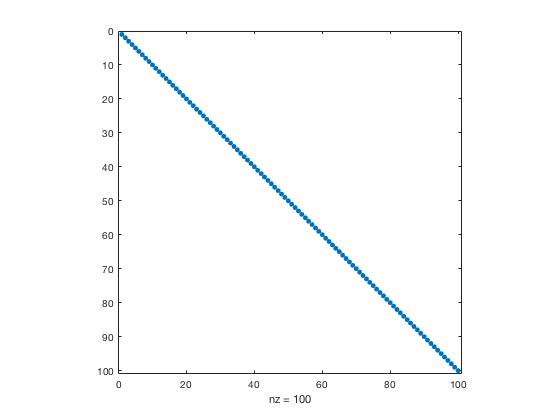

indice_cond = 81.5482

errore_rel = 0

numiter = 2

resid_rel = 0

[indice_cond,errore_rel,numiter,resid_rel] = CalcoloAccuratezza(A,x,eps,700)

## **Test con Matrice A con diagonale strettamente dominante **$\rho \left(A\right)\le \left\|A\right\|$.

La matrice ha diagonale principale strettamente dominante. Questa è una condizione sufficiente per la convergenza dell'algoritmo. Si sono richieste almeno 13 cifre significative corrette e al massimo 900 iterazioni.

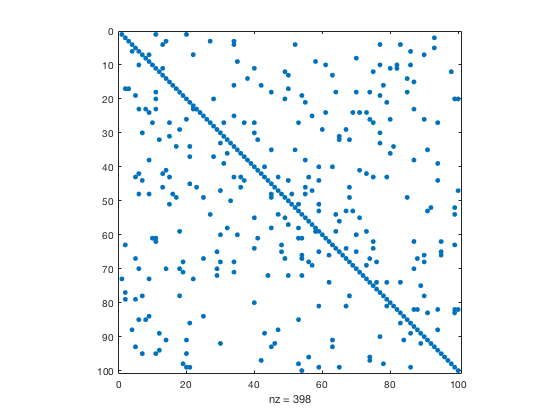

indice_cond = 7.8606

errore_rel = 8.4531e-15

numiter = 44

resid_rel = 8.2815e-15

A = sprand(100,100,0.03)+spdiags(ones(100,1),0,100,100)*3;
x = ones(100,1);
[indice_cond,errore_rel,numiter,resid_rel] = CalcoloAccuratezza(A,x,10^-13,900)

## **Test con Matrice  Malcondizionata e Sparsa '685_bus'**

Questa matrice è stata prelevata dal seguente indirizzo web:

[HB_685_bus](https://sparse.tamu.edu/HB/685_bus)

La matrice di input rappresenta un problema di rete elettrica avvenuto in Russia nel Luglio del 1985. Il numero degli zeri indica le interruzioni di corrente elettrica nei vari luoghi.

*N.B : Il parametro 'Problem' estrae una struttura dal file .mat caricato, per caricare la matrice A basta eseguire il comando A = Problem.A*

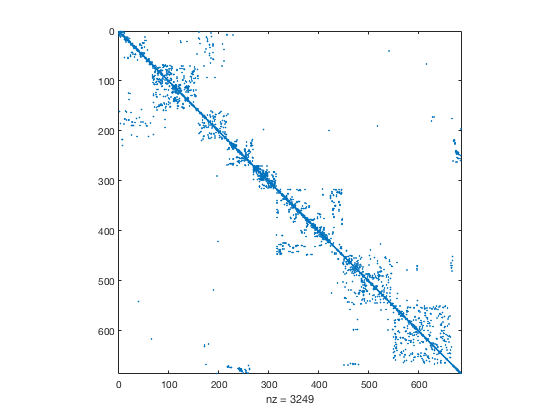

indice_cond = 5.3104e+05

errore_rel = 2.9550

numiter = 800

resid_rel = 1.5331e-04

load('685_bus.mat','Problem');
A = Problem.A;
x = ones(length(A),1);
[indice_cond,errore_rel,numiter,resid_rel] = CalcoloAccuratezza(A,x,eps,800)

L'errore relativo è circa 3, dunque non c'è nessuna cifra significativa corretta anche se ne abbiamo richieste 16 settando `TOL=eps`. Questo fenomeno avviene a causa del valore di condizionamento della matrice utilizzata.

## **Test con matrice A tridiagonale**

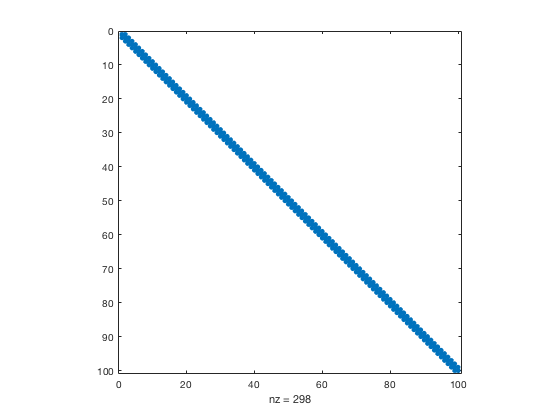

indice_cond = 22.3333

errore_rel = 1.7315e-09

numiter = 213

resid_rel = 1.7269e-09

A = gallery('tridiag',100,10,35,22);
x = ones(100,1);
[indice_cond,errore_rel,numiter,resid_rel] = CalcoloAccuratezza(A,x,10^-8,900)

## **Test con Matrice A di Poisson**

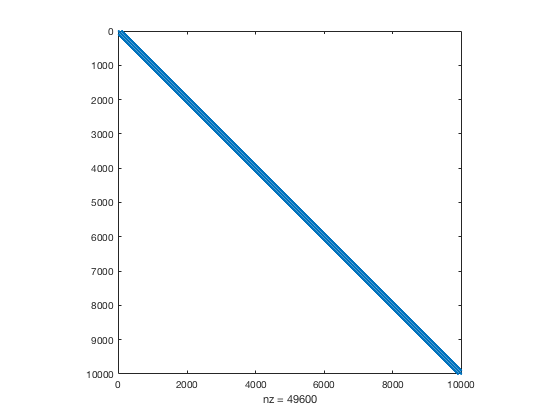

indice_cond = 6.0107e+03

errore_rel = 4.0667e-07

numiter = 30000

resid_rel = 3.8955e-09

A = gallery('poisson',100);
x = ones(10000,1);
[indice_cond,errore_rel,numiter,resid_rel] = CalcoloAccuratezza(A,x,10^-12,30000)

Contrariamente al caso della `matrice 685_bus` nella quale non vi era nessuna cifra significativa corretta nella soluzione, per la matrice di Poisson si nota che le cifre significative corrette restituite dalla soluzione sono 7 a fronte delle 12 che sono state richieste. 

**Esecuzione da interfaccia grafica**

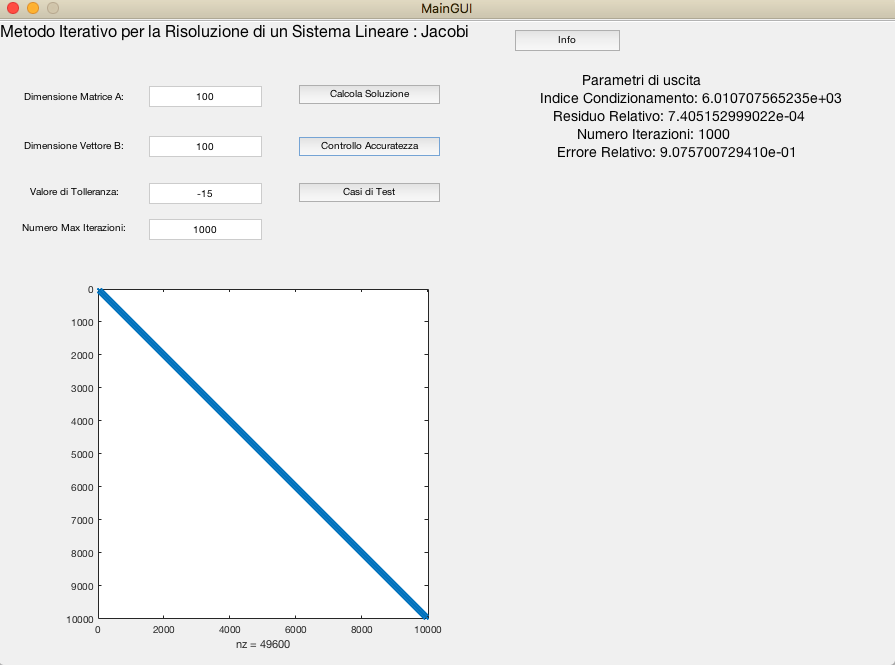

# Valutazione delle Performance

La valutazione delle performance dell'algoritmo mostra le differenze del metodo di Jacobi implementato con la funzione del MATLAB `bicg`. Entrambe richiedono gli stessi parametri di input (Matrice A, Vettore B , Tolleranza e Numero massimo di Iterazioni) e gli stessi parametri di Output (soluzione,numero iterazioni e residuo relativo). Le differenze tra i due metodi vengono mostrate su dei grafici che riportano il numero di iterazioni, l'indice di condizionamento della matrice in input ed errore e residuo relativo.

Sono stati scelti i seguenti parametri di input

- `A` : Matrice Sparsa di Poisson (presa dalla Gallery)

- `b `: Vettore casuale di elementi della stessa lunghezza di A

- `TOL` : Espresso come vettore di tolleranze da ${10}^{-1} \;a\;\mathrm{eps}$

- `MAXITER` : Numero massimo di iterazioni posto di default a 900

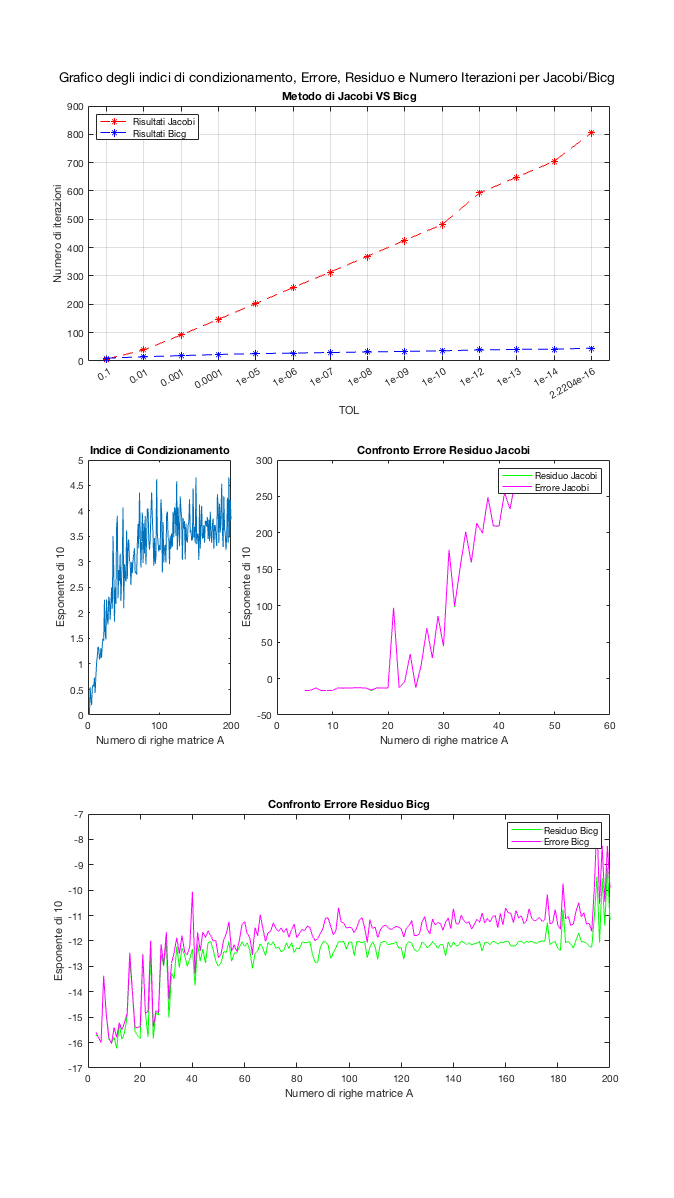

A = gallery('poisson',10);
b = sprand(length(A),1,0.2);
TOL=[10^-1 10^-2 10^-3  10^-4 10^-5 10^-6 10^-7 10^-8 10^-9 10^-10 10^-12 10^-13 10^-14 eps];
MAXITER = 900;
Valuta_Performance(A,b,TOL,MAXITER)

# Test di Robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 15 ,implementati in una classe definita dal matlab *matlab.unittest.TestCase*. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Di seguito seguono i casi di test più rilevanti che sono stati effettuati.

## Test Case 3

Verifica se la tolleranza e il numero massimo di iterazioni non sono specificati

**Input**

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = non specificato

- MAXITER = non specificato

## **Test Case 5**

Verifica se la matrice immessa non è sparsa

**Input**

- A = rand(10);

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 700;

## **Test Case 7**

Verifica se la matrice presenta uno zero sulla diagonale principale

**Input**

- A = sprand(10,10,0.1) + speye(10,10);

- A(1,1) = 0;

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 700;

## Test Case 8

Verifica se il vettore B non è un vettore

**Input**

- A = sprand(10,10,0.1) + speye(10,10);

- b = rand(10);

- TOL = 10^-8;

- MAXITER = 700;

## Test Case 11

Verifica se il valore di tolleranza è negativo

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = -3;

- MAXITER = 10500;

## Test Case 13

Verifica se il numero massimo di iterazioni è molto grande

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 10500;

## Test Case 15

Verifica che il numero di iterazioni è pari a MAXITER

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 3;

## Esecuzione Test suite

Vengono effettuati i test a partire dagli input definiti in precedenza.

result = runtests('CasiTest.m')

Running CasiTest
.......... .....
Done CasiTest
__________



result =   1×15 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   15 Passed, 0 Failed, 0 Incomplete.
   1.377 seconds testing time.


table(result)

ans = 15×6 table
            Name             Passed    Failed    Incomplete    Duration       Details   
    _____________________    ______    ______    __________    _________    ____________

    'CasiTest/TestCase1'     true      false       false          0.4998    [1×1 struct]
    'CasiTest/TestCase2'     true      false       false        0.034552    [1×1 struct]
    'CasiTest/TestCase3'     true      false       false         0.34687    [1×1 struct]
    'CasiTest/TestCase4'     true      false       false        0.045258    [1×1 struct]
    'CasiTest/TestCase5'     true      false       false        0.068731    [1×1 struct]
    'CasiTest/TestCase6'     true      false       false        0.031101    [1×1 struct]
    'CasiTest/TestCase7'     true      false       false        0.

## Riferimenti

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

- [Docenti.unina.it D'alessio Alessandra](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

- [Wikipedia : Metodo di Jacobi](https://it.wikipedia.org/wiki/Metodo_di_Jacobi)

## **Autori**

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***